# **第二章 数据清洗**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

## **2.1 数据清洗简介**

        数据清洗（Data Cleaning）是数据预处理的一个重要环节，它涉及检测、纠正或删除数据集中的错误和不一致的数据。在现实世界中收集的数据常常是不完整的、不一致的，或者含有很多错误和误差，数据清洗的目的就是通过各种方法改善数据质量，使其更适合进行数据分析或建模。

        数据清洗虽然是一个费时且可能复杂的过程，但它在整个数据分析和数据科学的过程中发挥着至关重要的作用。通过有效的数据清洗，可以确保数据分析的准确性和有效性。

        在以往的机器学习建模过程中，人们大多采用Model-Centric AI的思路开展工作，关注的焦点大多集中在模型上面，即：若采用A模型无法取得理想的结果时，会尝试不同的模型，期望能够取得更好的结果。但是，实际上，在机器学习领域中有一句经典的谚语：“garbage in, garbage out”，也就是说，如果数据质量比较差的话，那么无论采用什么模型，都难以取得较为满意的结果。

        近年来，Data-Centric AI的建模思路得到了越来越多的人的关注。Data-Centric AI与Model-Centric AI的主要区别如图1所示。

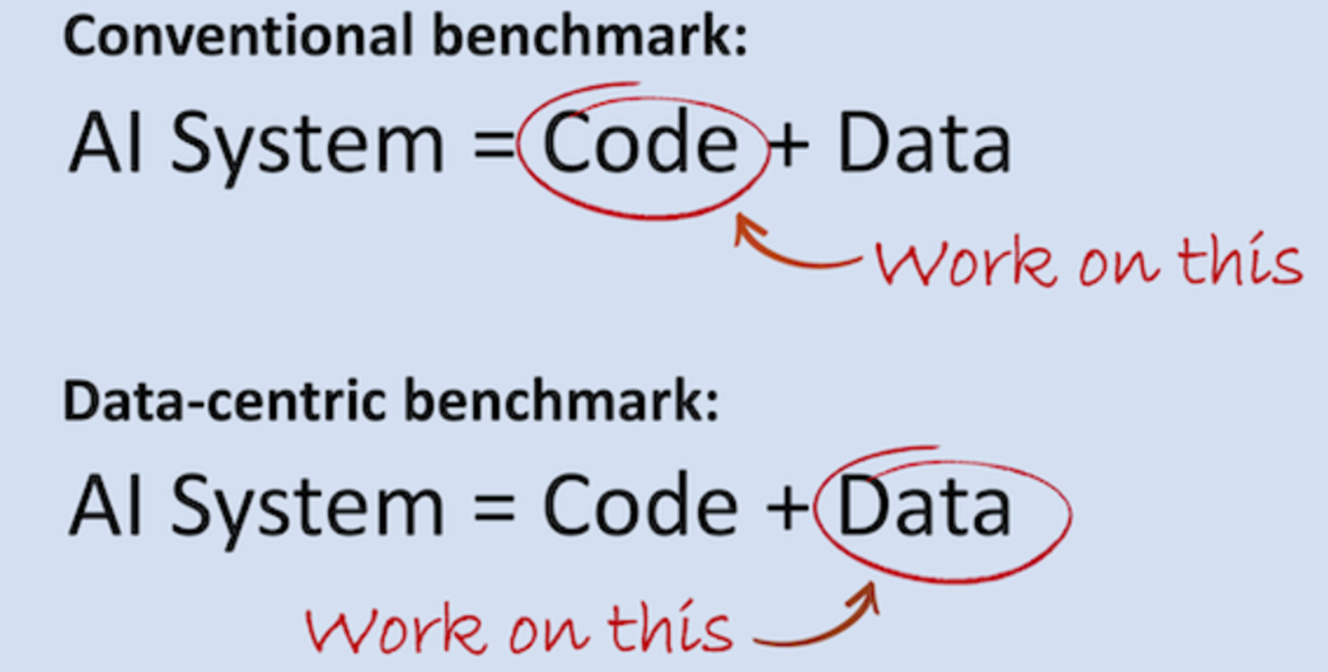  

图1 Data-Centric AI与Model-Centric AI的主要区别

        在实际的建模工作中，应采取Data-Centric AI与Model-Centric AI相结合的建模思路，如图2所示。当我们发现模型的性能不太理想时，一方面应仔细检查数据质量部分是否可以进一步改善，另一方面可以尝试其他的建模方法。

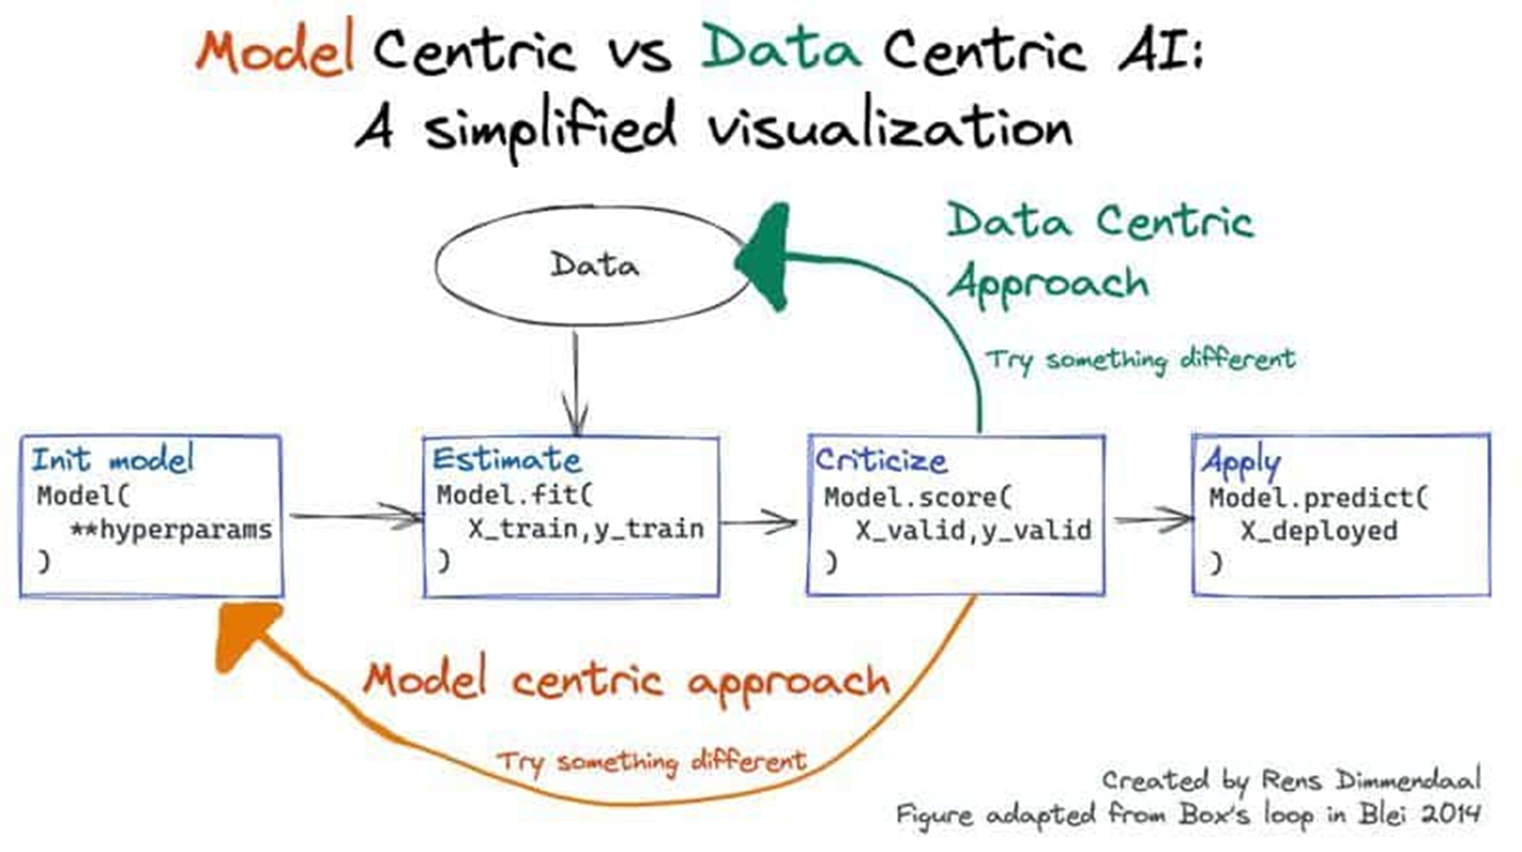

图2 Data-Centric AI与Model-Centric AI相结合的建模思路

        数据清洗通常包括如下几个方面的内容：

- **缺失值处理：**数据集中可能存在缺失值，数据清洗需识别这些值，并决定如何处理它们，比如填充、删除或插值。

- **异常值检测与处理：**异常值是指明显偏离其他数据点的值。需要检测这些值，并确定它们是真正的异常还是数据输入错误，然后决定保留、删除或更正。

- **一致性检查：**确保数据在格式和逻辑上保持一致性，例如日期格式统一、类别标签的一致性等。

- **数据格式化：**将数据转换成适合分析的格式，包括统一不同来源的数据格式、转换数据类型等。

- **数据清理：**涉及删除重复项、更正错误、验证和纠正数据的完整性。

- **噪声数据处理：**噪声是指数据集中的随机错误或方差，清洗过程包括平滑数据以减少噪声。

## 2.2 案例1：基于Data Cleaner的噪声去除

- **导入数据**

        noise_data.mat文件中有一个table类型的变量T，共包含两列：T.x和T.y，其中T.y为含有噪声的正弦信号，如下图所示：

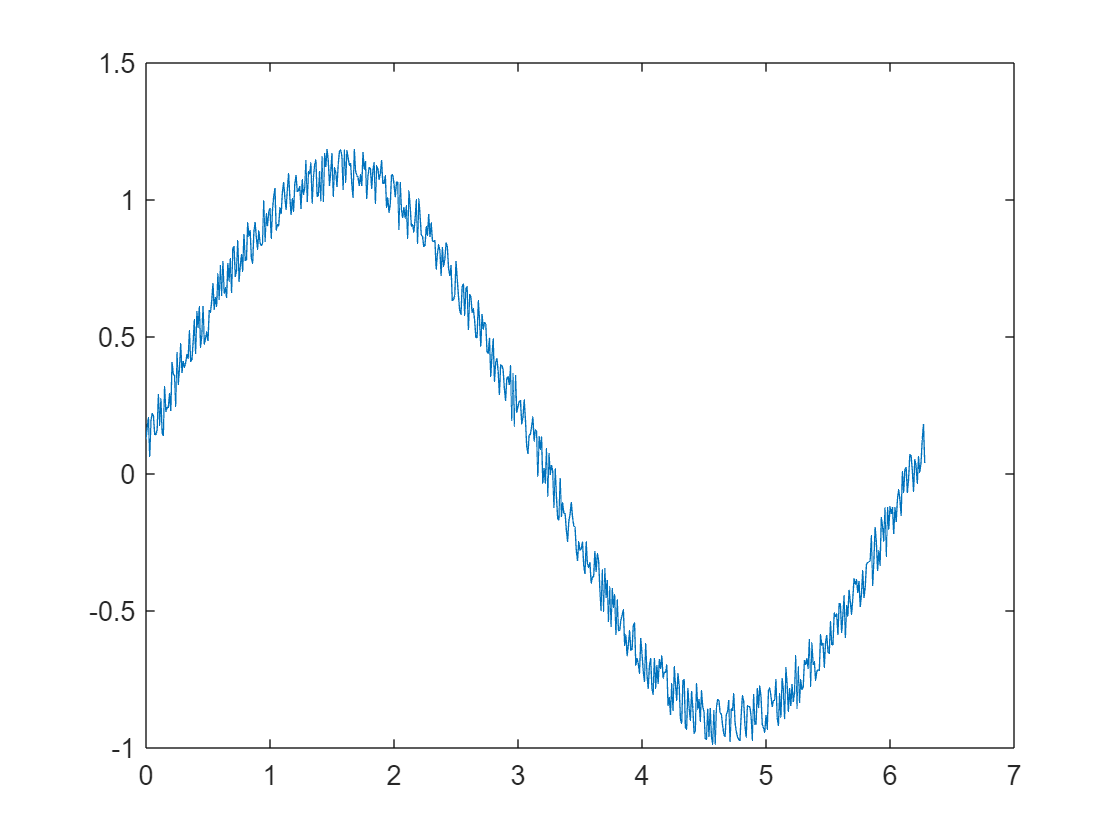

load noise_data.mat

% 绘图

figure
plot(T.x, T.y)

- **利用Data Cleaner APP去除噪声**

        利用MATLAB中内置的“Data Cleaner”APP，可以方便地帮助我们对数据进行预处理。可以通过在Command Window中输入“dataCleaner”命令，或者在APPS菜单中点击打开，如图3所示。

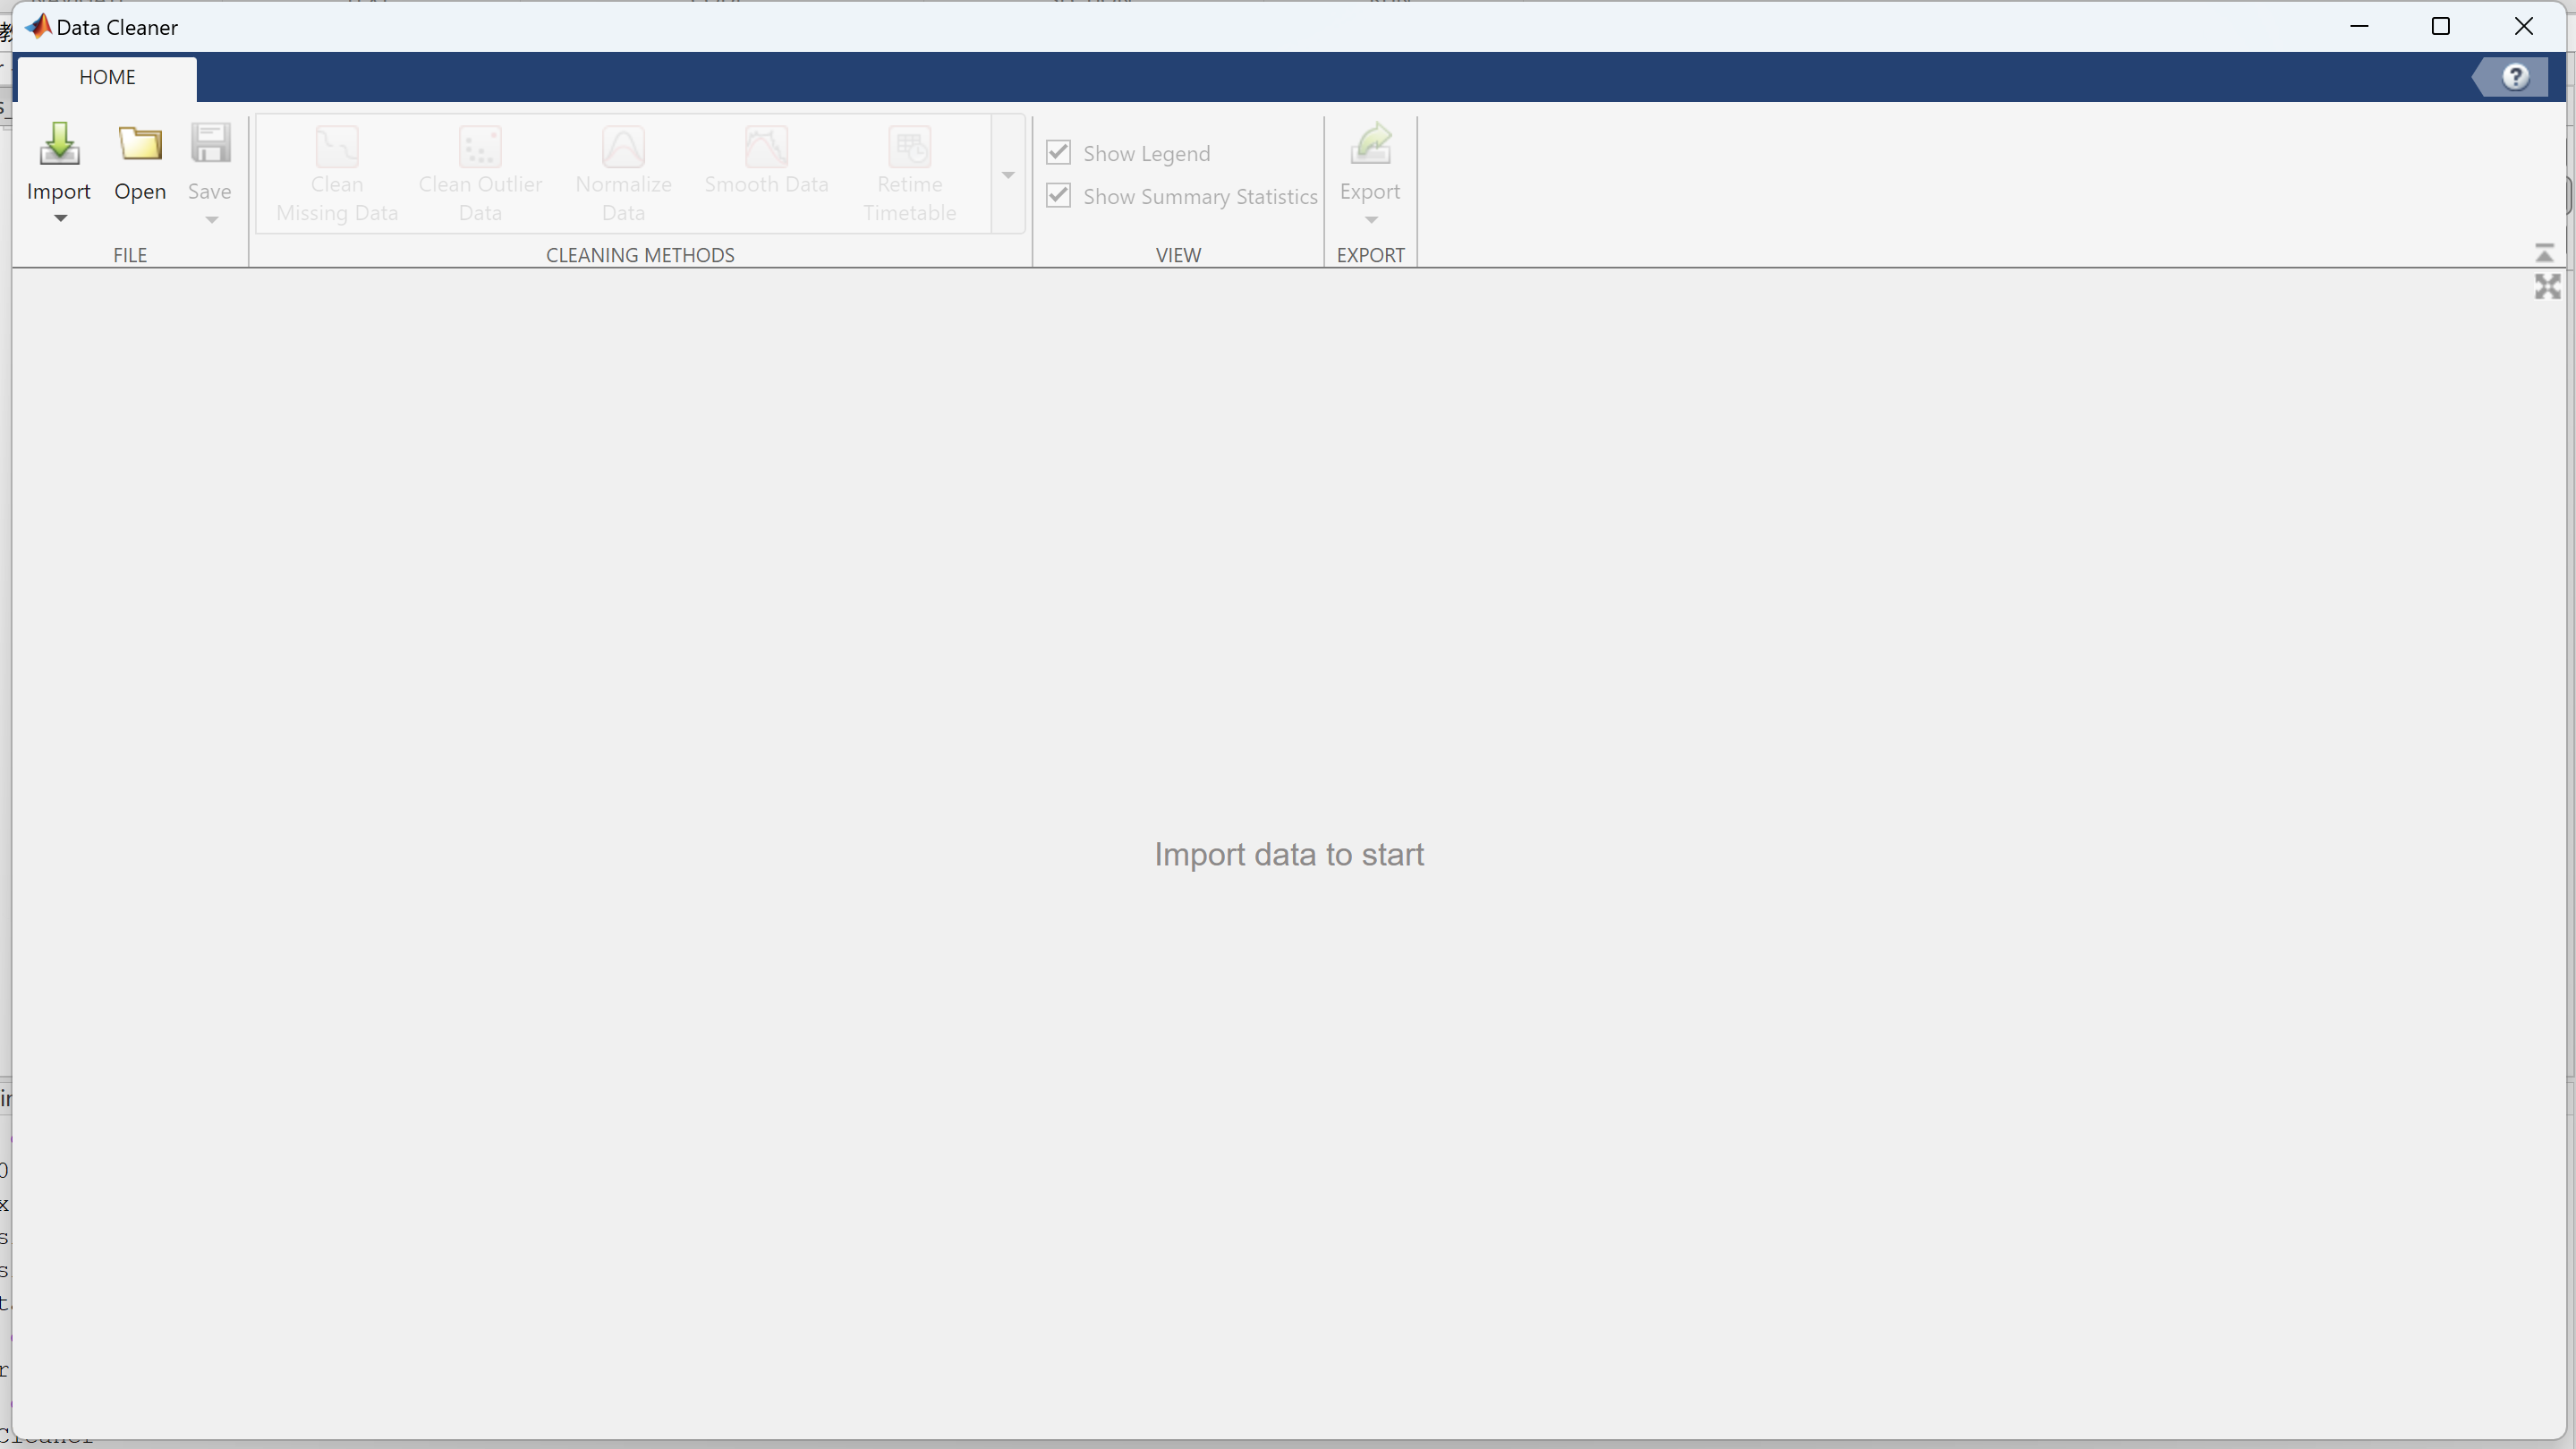

图3 Data Cleaner APP主界面

        点击左上角的【Import】或【Open】按钮，从Workspace中选择需要导入的变量（注意：必须是table类型），或者从弹出的对话框中选择需要导入的数据文件，均可将数据导入到Data Cleaner中，如图4所示。

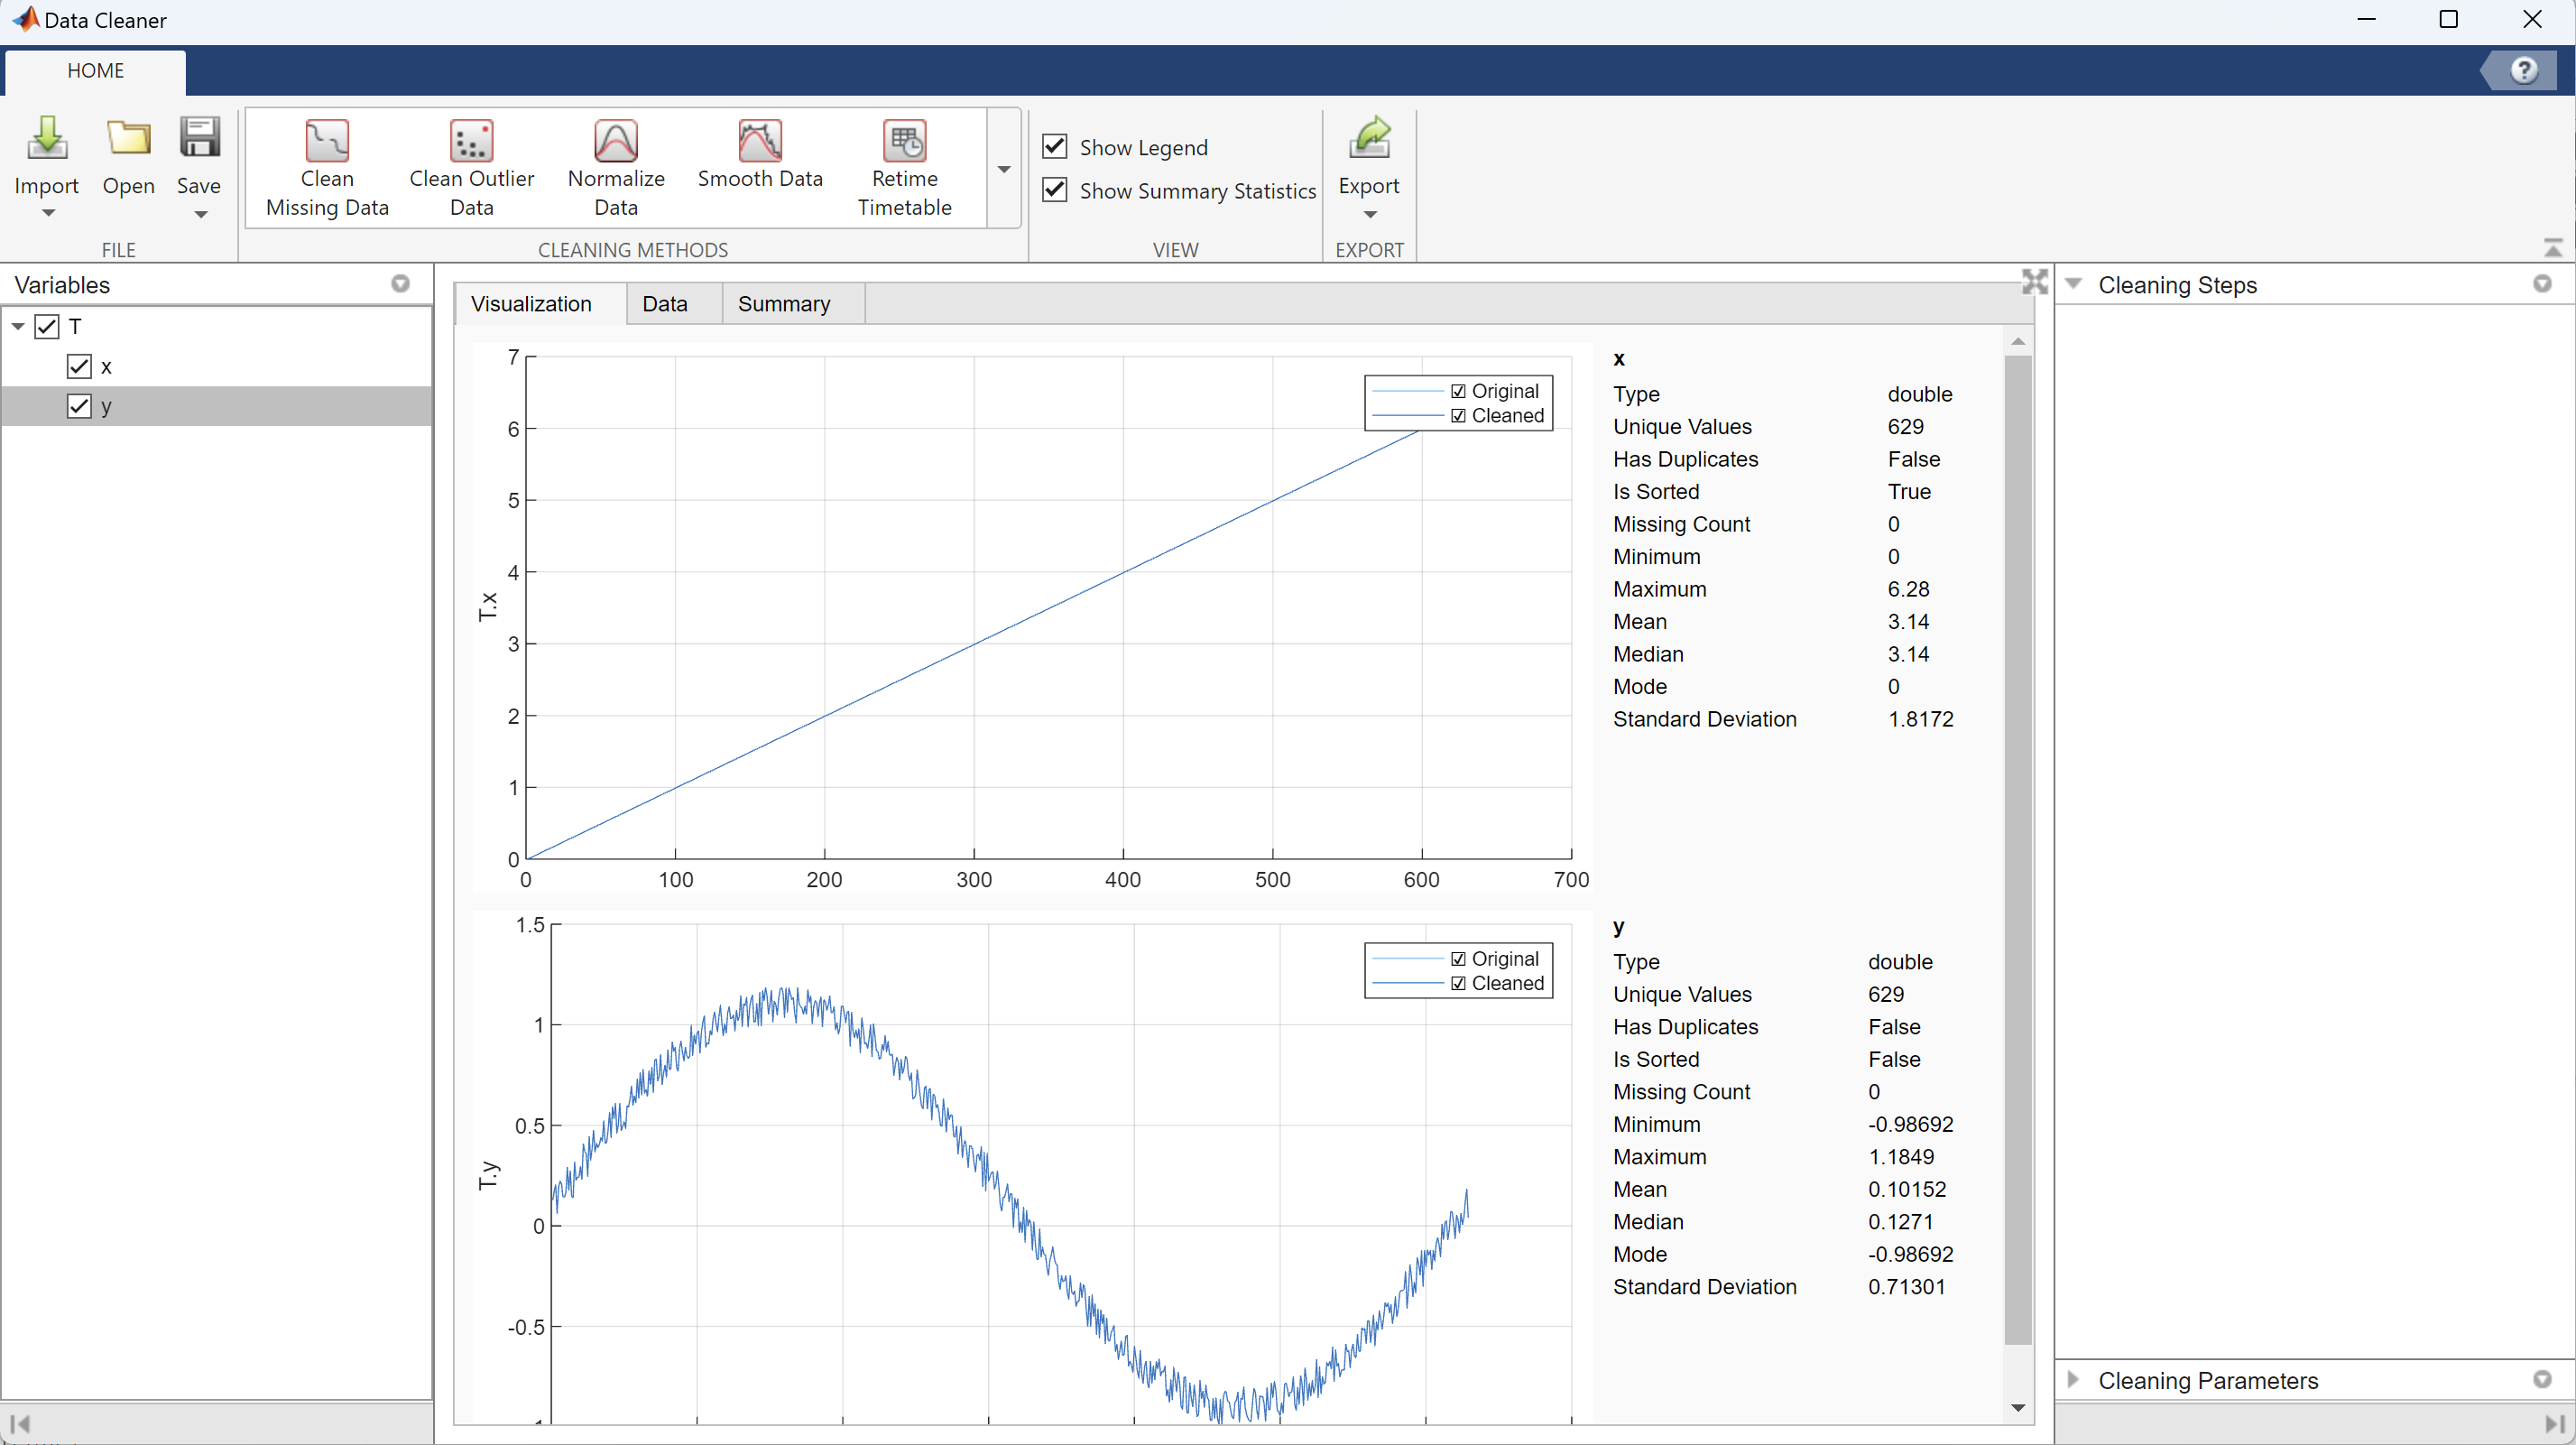

图4 Data Cleaner导入数据

        从上方的菜单中点击【Smooth Data】按钮，右侧的窗口中在Smooth Method下拉菜单中选择【Savitzky-Golay polinomial filter】，如图5所示。

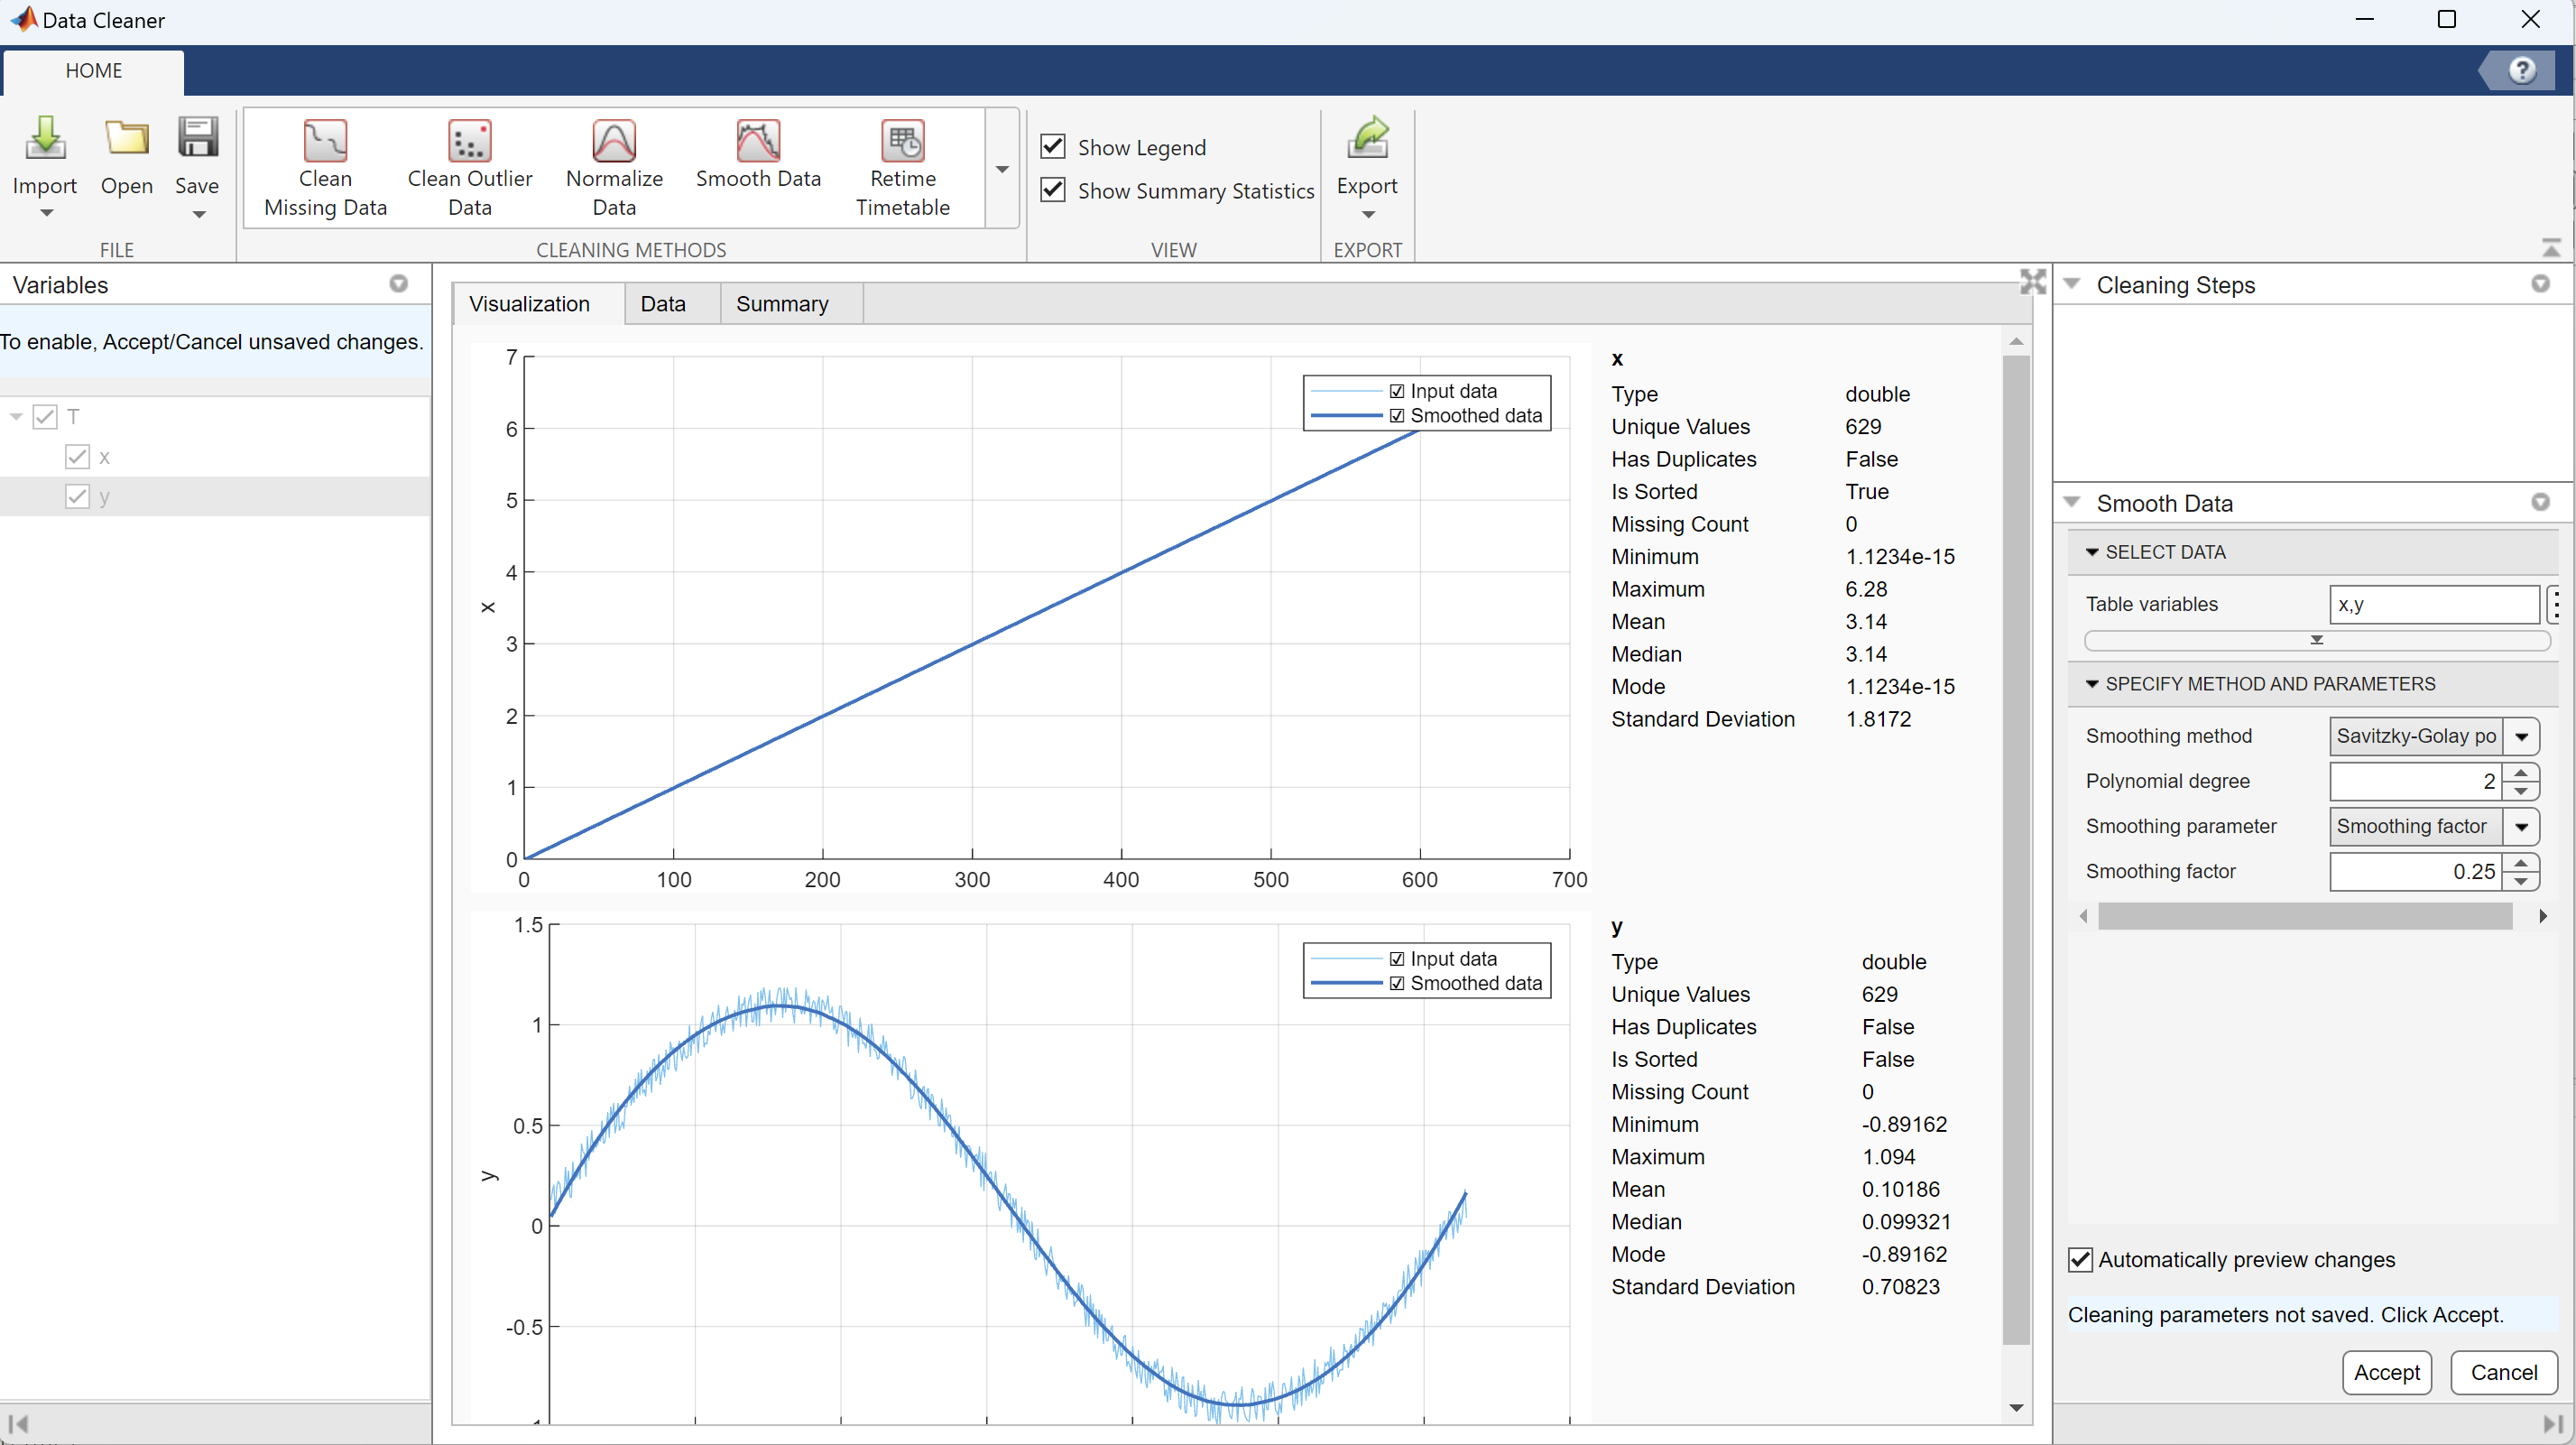

图5 Savitzky-Golay多项式平滑

        点击【Accept】按钮后，再点击上方的【Export】按钮，即可将平滑后的结果保存到Workspace中。

## 2.3 案例2：基于Data Cleaner的异常值处理

- **导入数据**

        outlier_data.mat文件中有一个table类型的变量T，共包含两列：T.x和T.y，其中T.y为含有异常值及噪声的正弦信号，如下图所示：

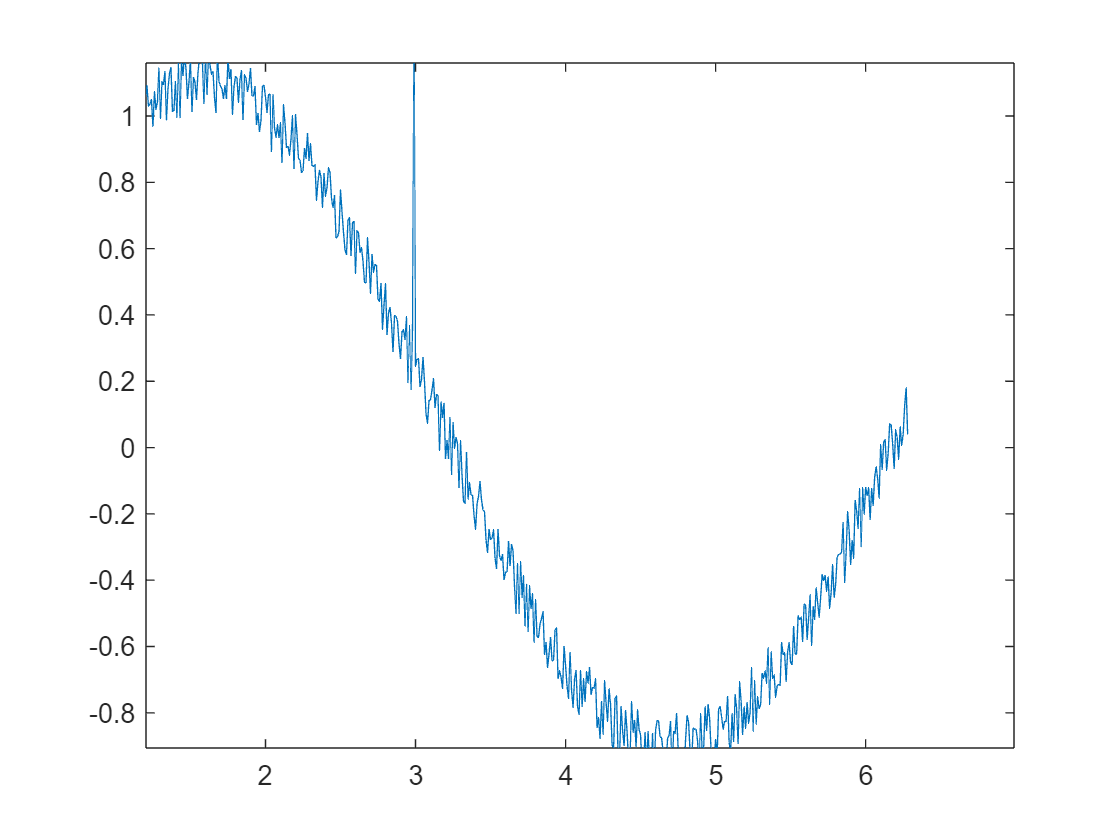

load outlier_data.mat

% 绘图
figure

plot(T.x, T.y)

- **利用Data Cleaner APP去除异常值**

        与案例1类似，打开Data Cleaner APP后，首先将数据导入，从上方的菜单中点击【Clean Outlier Data】按钮，右侧的窗口中在Detection Method下拉菜单中选择【Moving median】，Window length下拉菜单中将值设置为9，如图6所示。

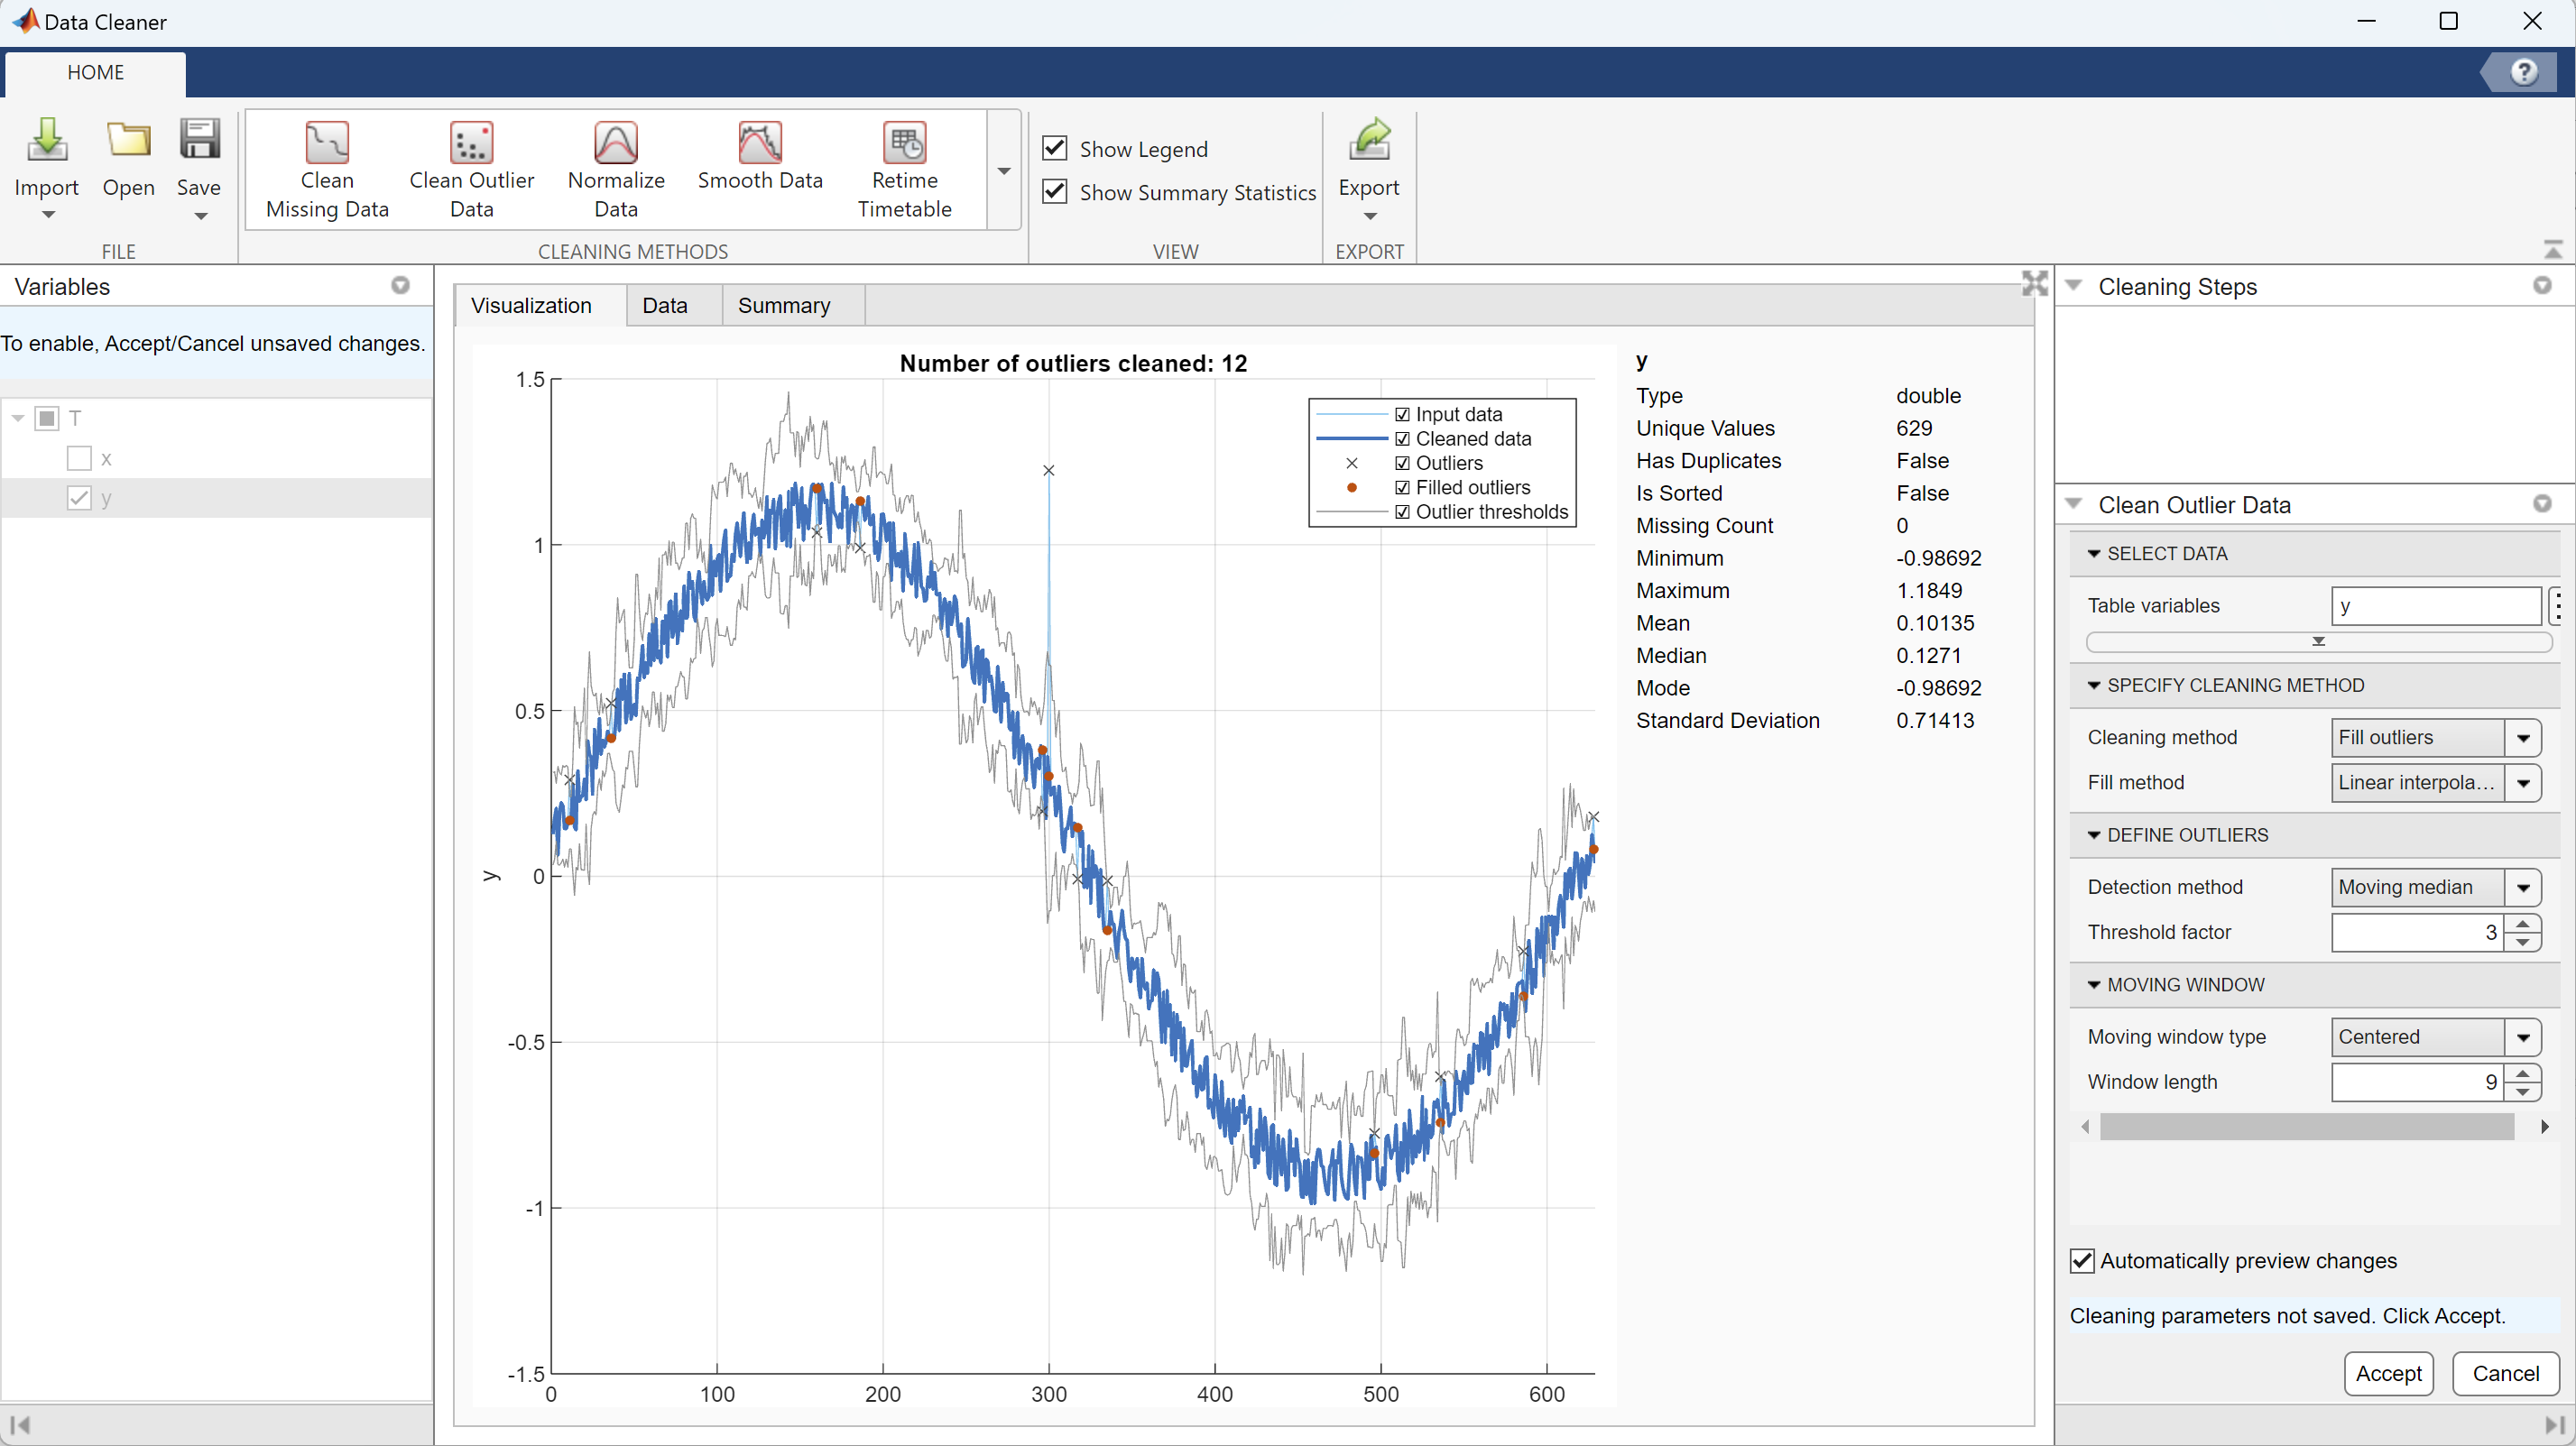

图6 Moving median检测异常值

         点击【Accept】按钮后，再点击上方的【Export】按钮，即可将平滑后的结果保存到Workspace中。

## 2.4 案例3：基于Data Cleaner的缺失值处理

- **导入数据**

        missing_data.mat文件中有一个table类型的变量T，共包含两列：T.x和T.y，其中T.y为含有缺失值及噪声的正弦信号，如下图所示：

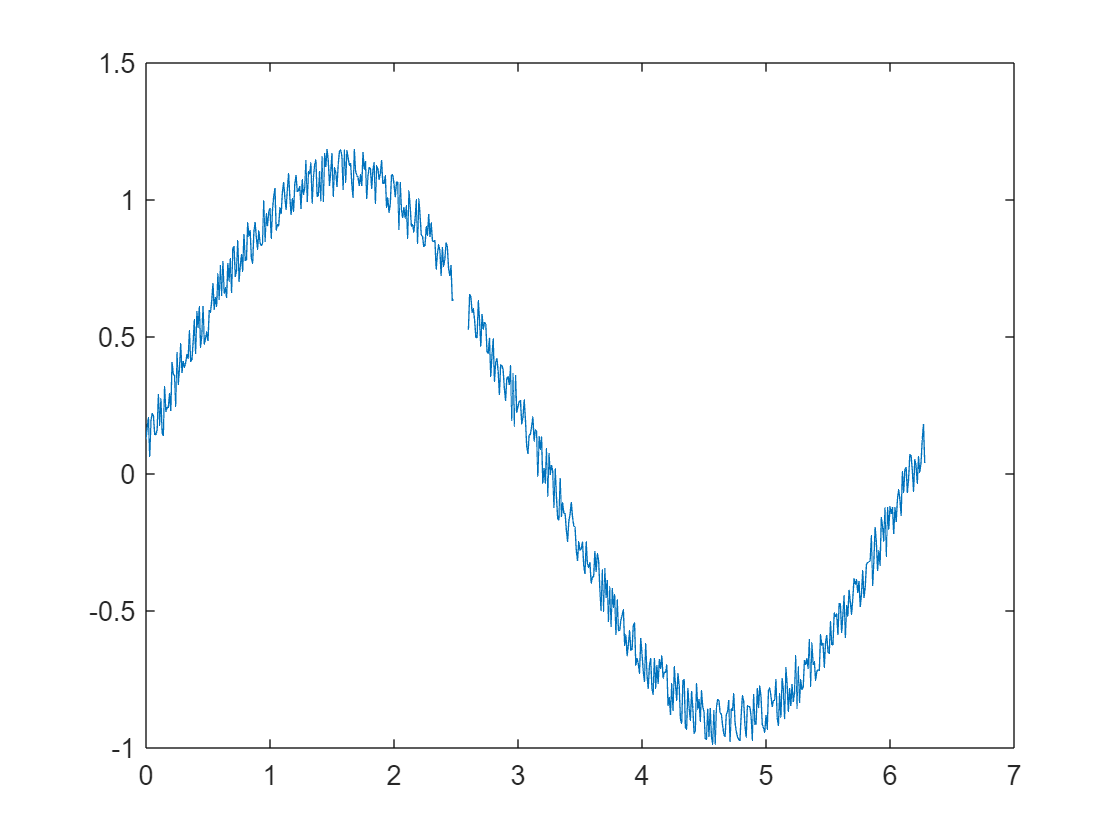

load missing_data.mat

% 绘图
figure
plot(T.x, T.y)

- **利用Data Cleaner APP填充缺失值**

        与案例1类似，打开Data Cleaner APP后，首先将数据导入，从上方的菜单中点击【Clean Missing Data】按钮，右侧的窗口中在Fill Method下拉菜单中选择【Modified Akima Cubic Interpolation】，如图7所示。

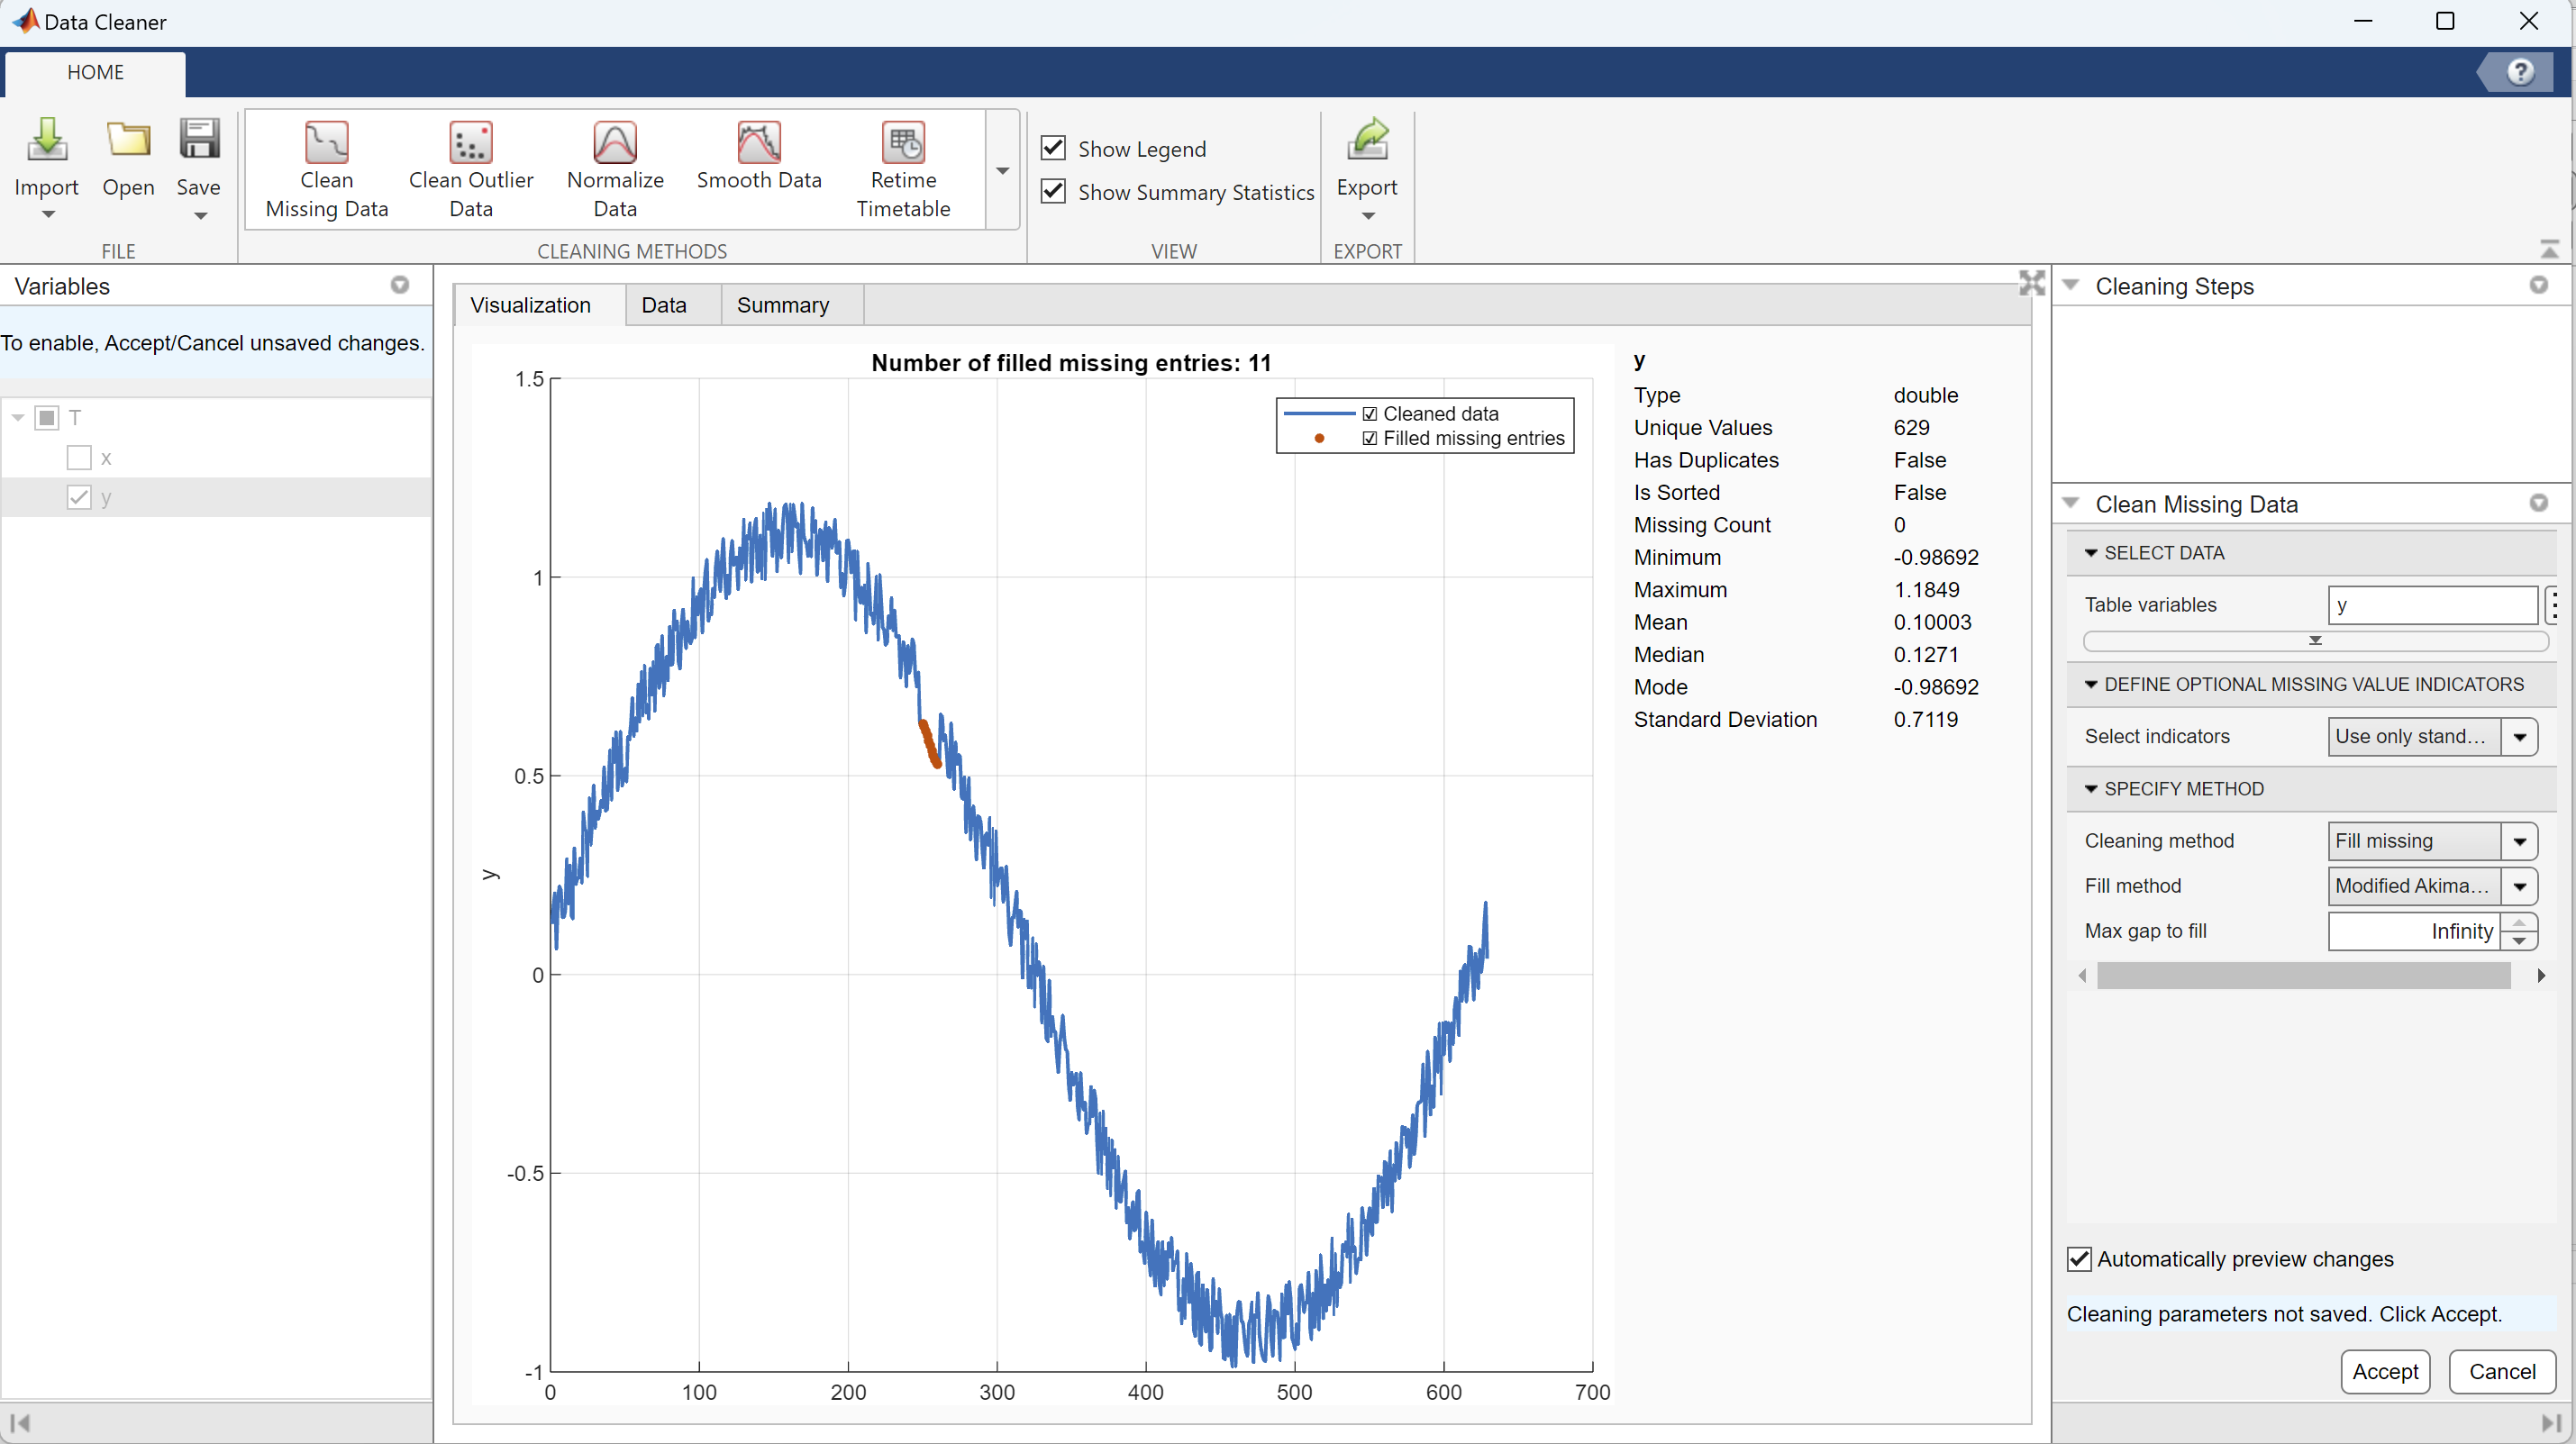

图7 Modified Akima Cubic Interpolation填充缺失值

        点击【Accept】按钮后，再点击上方的【Export】按钮，即可将平滑后的结果保存到Workspace中。

## 2.5 案例4：基于Data Cleaner的数据归一化

- **导入数据**

        raw_data.mat文件中有一个table类型的变量T，共包含三列：T.x、T.y和T.z，其中T.y和T.z为幅值范围存在数量级差的正弦信号和余弦信号，如下图所示：

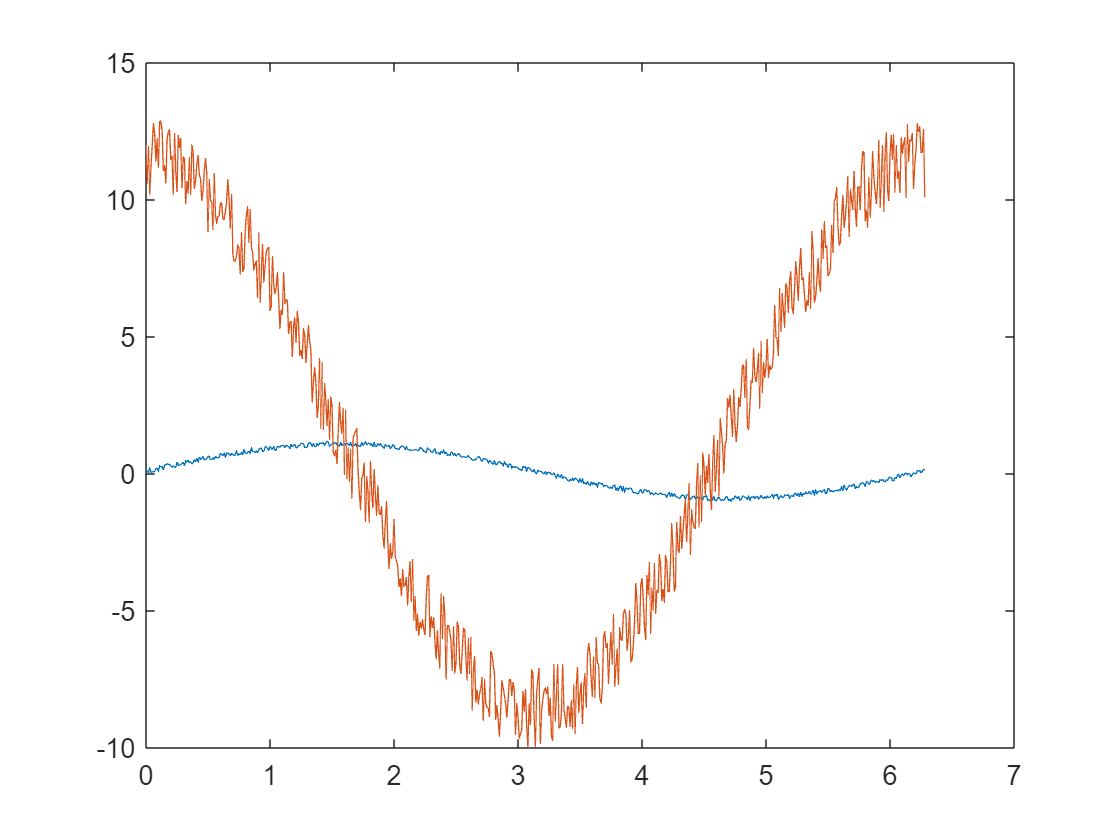

load raw_data.mat

% 绘图
figure
plot(T.x, T.y)
hold on
plot(T.x, T.z)

        从图中可以看出，正弦信号几乎被余弦信号淹没了。

- **利用Data Cleaner APP对数据进行归一化**

        与案例1类似，打开Data Cleaner APP后，首先将数据导入，从上方的菜单中点击【Normalize Data】按钮，右侧的窗口中在Normalization Method下拉菜单中选择【Range】，如图8所示。

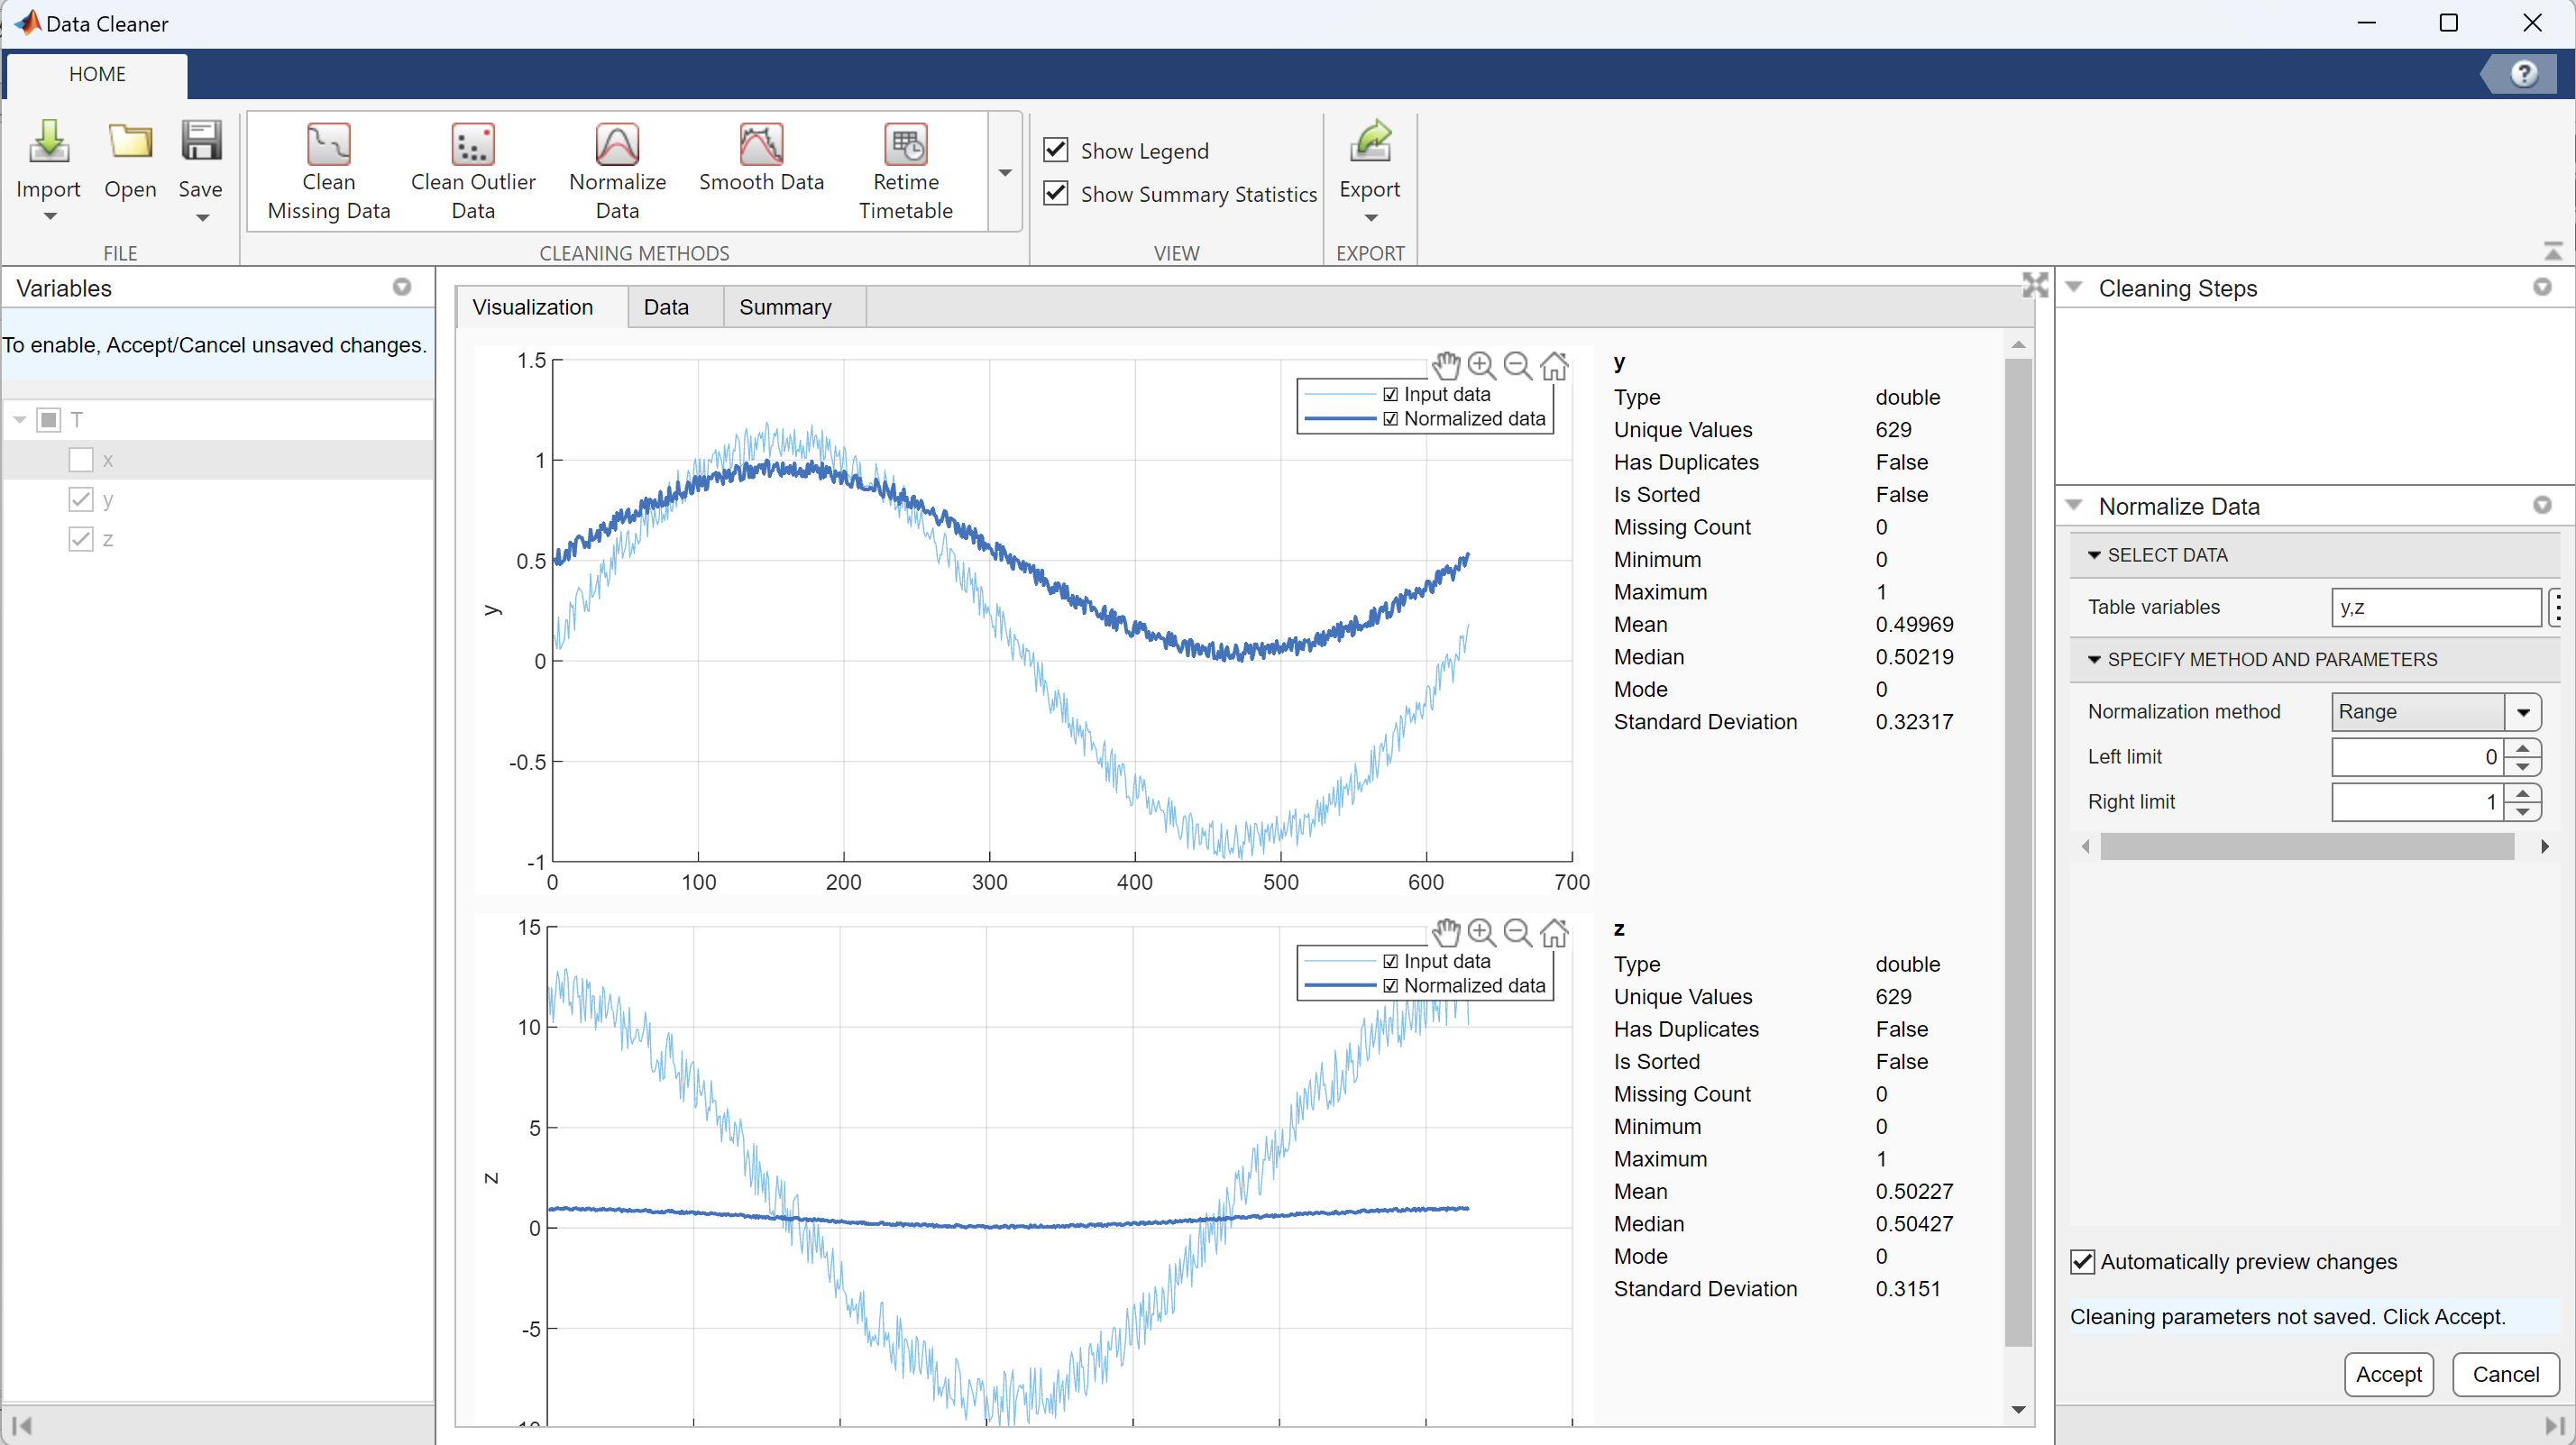

图8 MinMax数据归一化

  点击【Accept】按钮后，再点击上方的【Export】按钮，即可将平滑后的结果保存到mat文件中，这里我们保存到normalize_data.mat文件中。

- **绘图展示归一化之后的数据**

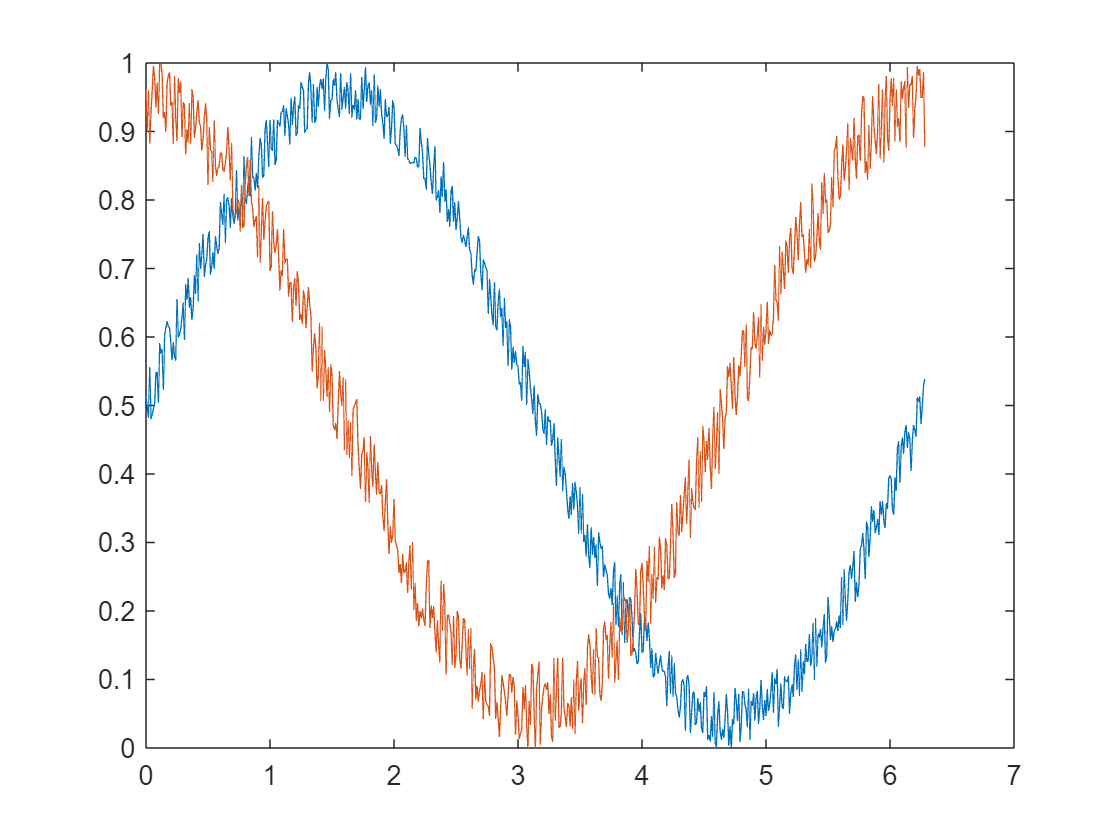

load normalize_data.mat

% 绘图
figure
plot(T1.x, T1.y)
hold on
plot(T1.x, T1.z)

        可以看出，正弦曲线和余弦曲线的范围都转换到了[0, 1]之间。